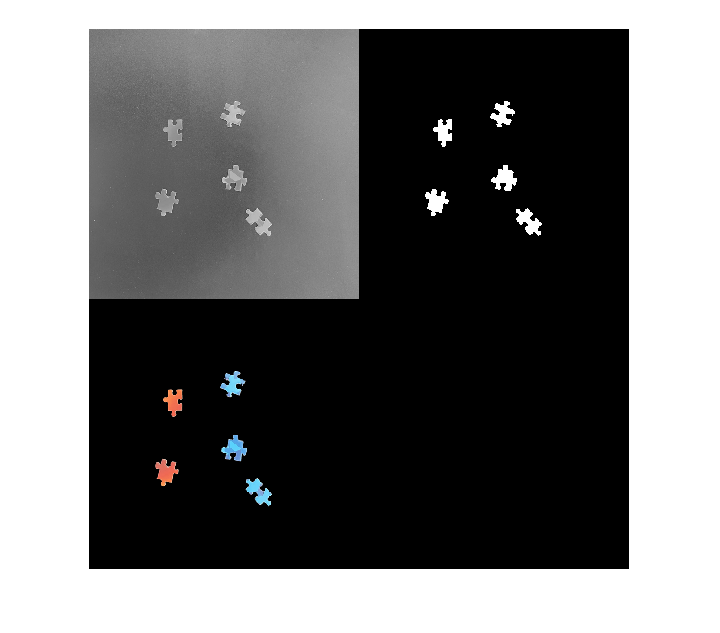

X0 = imread("Puzzle_06.jpg");
X = rgb2gray(X0);
BW = imbinarize(X, 'adaptive', 'Sensitivity', 0.500000, 'ForegroundPolarity', 'bright');

% Open mask with disk
radius = 3;
decomposition = 0;
se = strel('disk', radius, decomposition);
BW = imopen(BW, se);

% Create masked image.
maskedImage = X0;
maskedImage(repmat(~BW,1,1,3)) = 0;
montage({X,BW,maskedImage})


K = 3;
labels = imsegkmeans(maskedImage,K)

labels = 1512×1512 uint8 matrix
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1

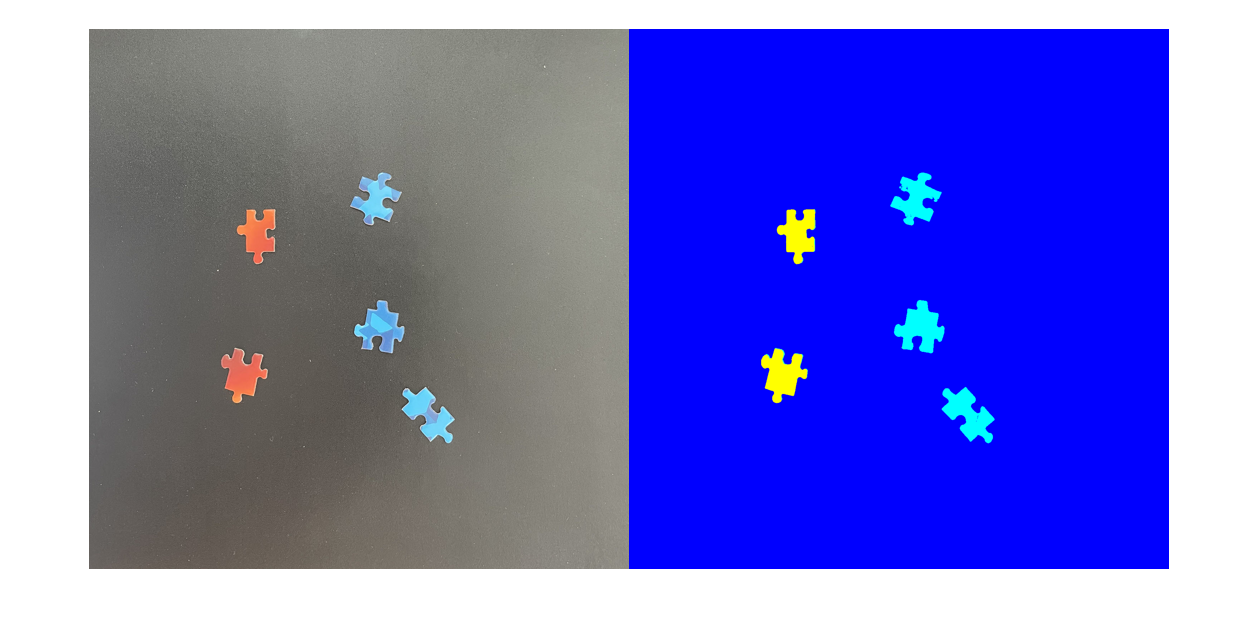

montage({X0,label2rgb(labels)})